# Práctica 5: Filtros Espaciales 

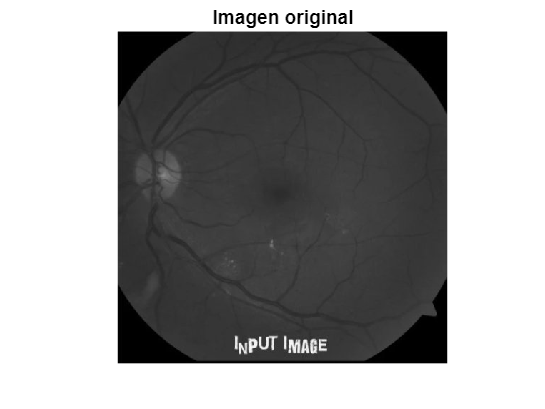

% Cargar imagen
imagen = imread("ojo.jpg");

% Mostrar imagen original
imshow(imagen);
title('Imagen original')

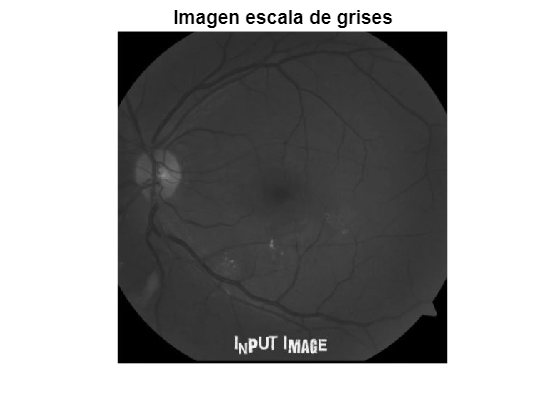


% Mostrar imagen escala de grises
imagen_rgb = rgb2gray(imagen);
imshow(imagen_rgb);
title('Imagen escala de grises')

### Definición de filtros

%Filtro pasa bajas 
lowpass = [2, 2, 2; 2, 10, 2; 2, 2, 2];
weight_lowpass = sum(lowpass(:));

%Filtro pasa altas
highpass = [-2, -2,-2; -2 24, -2; -2, -2, -2];
weight_highpass = sum(highpass(:));

new_imagen_rgb = imagen_rgb;

### Aplicar filtro pasa bajas

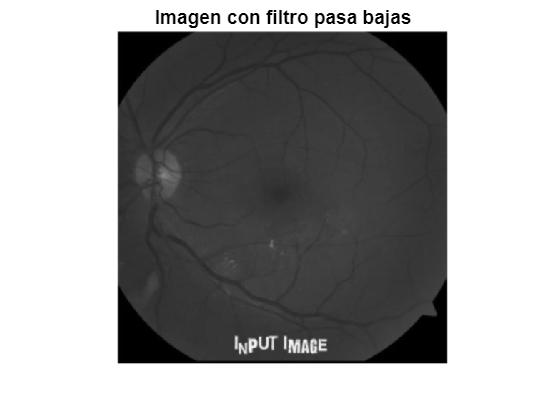

[fila, columna] = size(imagen_rgb);
imagen_rgb=double(imagen_rgb);

for x = 2:fila-1
    for y = 2:columna-1
        suma = 0;
        for i = -1:1
            for j = -1:1
                suma = suma + imagen_rgb(x+i,y+j)*lowpass(i+2, j+2);
            end
        end
        suma=double(suma)/weight_lowpass;
        new_imagen_rgb(x,y)=suma;
    end
end

imshow(uint8((new_imagen_rgb)));
title('Imagen con filtro pasa bajas')

### Aplicar filtro pasa altas

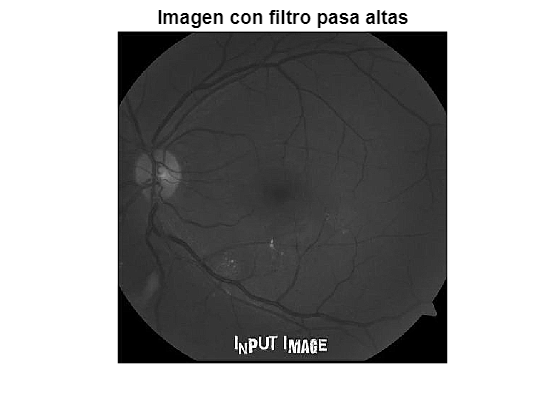

for x = 2:fila-1
    for y = 2:columna-1
        suma = 0;
        for i = -1:1
            for j = -1:1
                suma = suma + imagen_rgb(x+i,y+j)*highpass(i+2, j+2);
            end
        end
        suma=double(suma);
        suma=suma/weight_highpass;
        new_imagen_rgb(x,y)=suma;
    end
end

imshow(uint8(new_imagen_rgb));
title('Imagen con filtro pasa altas')